STA = [];
for i=1:22
    i
    fs = blwgn_meta_struct(i).moth.fs;
    try
        STA = [STA; blwgn_meta_struct(i).moth.STA];
    catch 
        continue;
    end
end

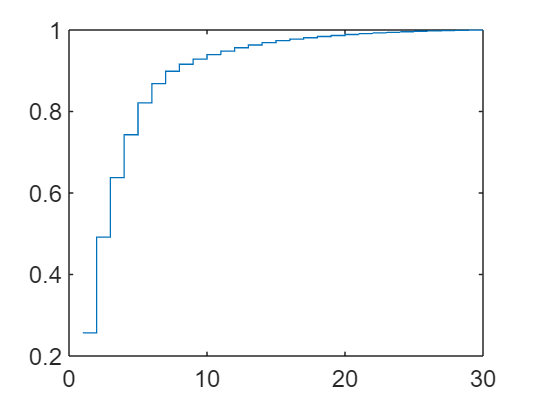

sta = cell2mat(T_STA_EV.STA);
[U,S,W] = svd(sta, 'econ');
evals = diag(S);
figure;
stairs(cumsum(evals)./sum(evals));

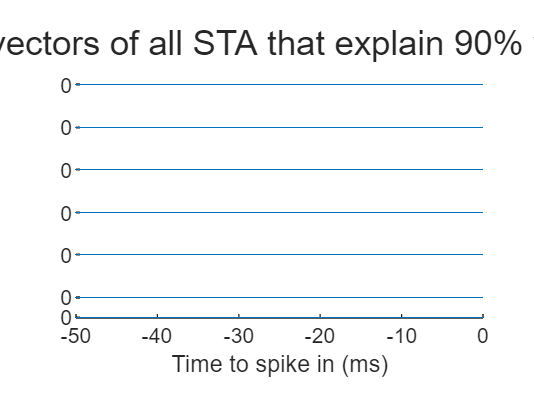

sig_evals = evals((cumsum(evals)./sum(evals)<=0.9));
figure;
t = linspace(-50,0,size(sta,2));
tiledlayout(length(sig_evals),1);
for i=1:length(sig_evals)
    % plot(t, sig_evals'.*W(:,1:length(sig_evals)))
    nexttile;
    plot(t, sig_evals(i).*W(:,i), 'LineWidth',1);
    box off
    set(gca().XAxis, 'Visible', 'off');
    set(gca, "YLimitMethod", "tickaligned")
end

set(gca().XAxis, 'Visible', 'on');
xlabel('Time to spike in (ms)');
sgtitle('Basis vectors of all STA that explain 90% variation');

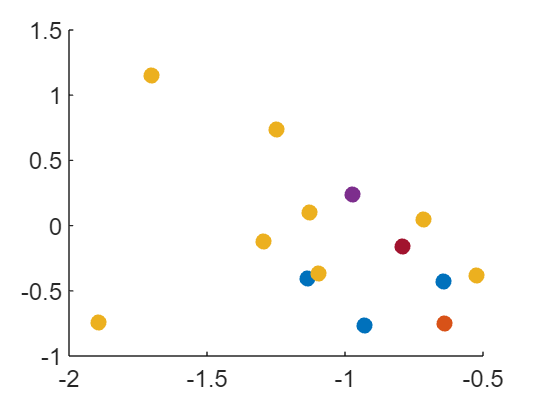

sta_few = sta(T_STA_EV.colorcode ~=10, :);
sta_proj_on_ev = sta_few * W(:,1:3);
figure;

% c = ["#0072BD" "#D95319" "#EDB120" "#7E2F8E" "#77AC30" "#4DBEEE"];

scatter(sta_proj_on_ev(:,1), sta_proj_on_ev(:,2),[],T_STA_EV.colorcode(T_STA_EV.colorcode~=10), 'filled');
colormap("lines");

% colorbar()

i = 1

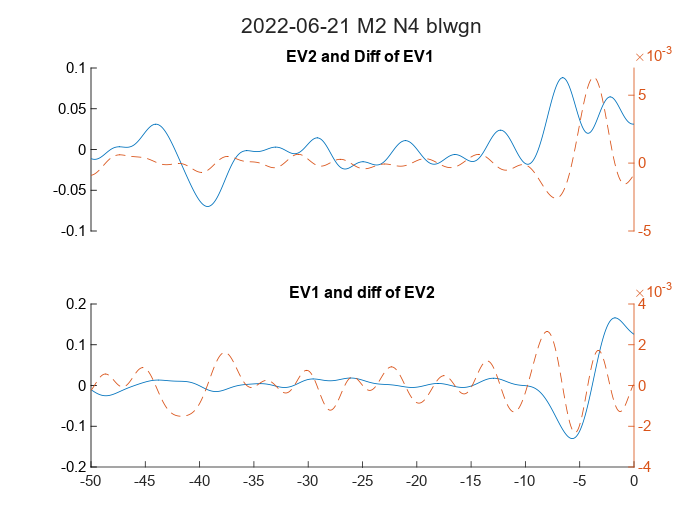

i = 2

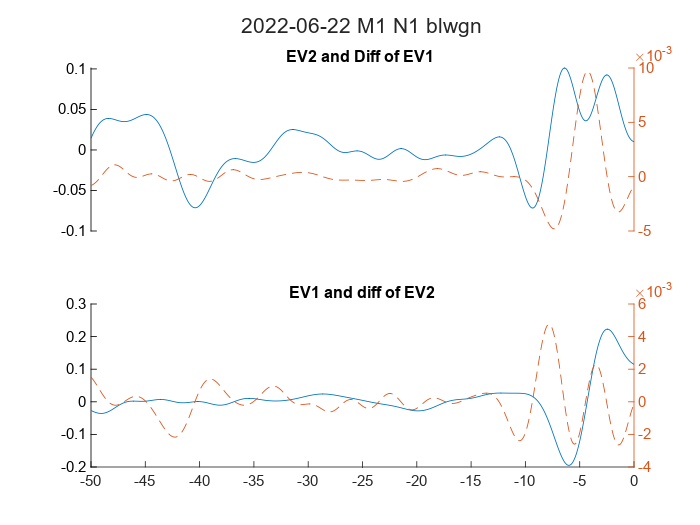

i = 3

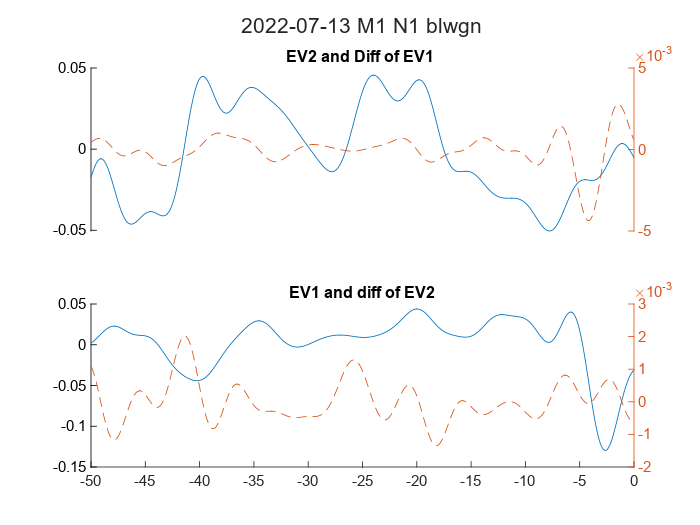

i = 4

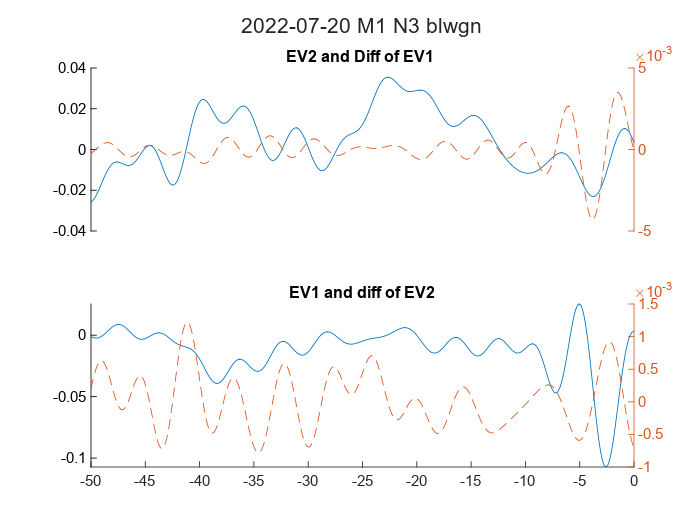

i = 5

i = 6

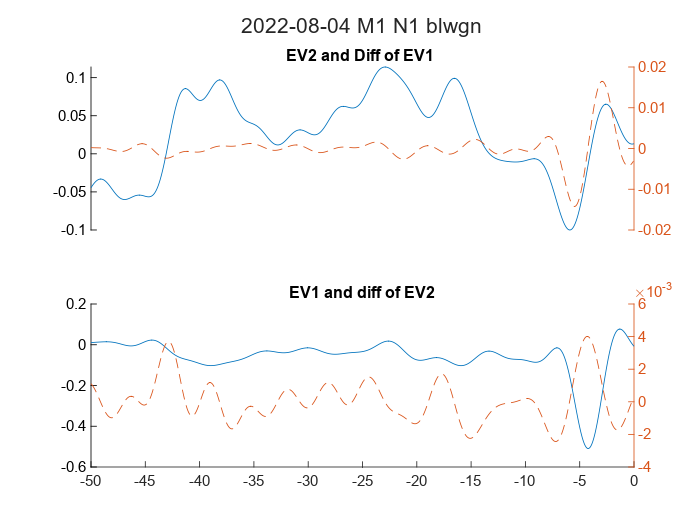

i = 7

i = 8

i = 9

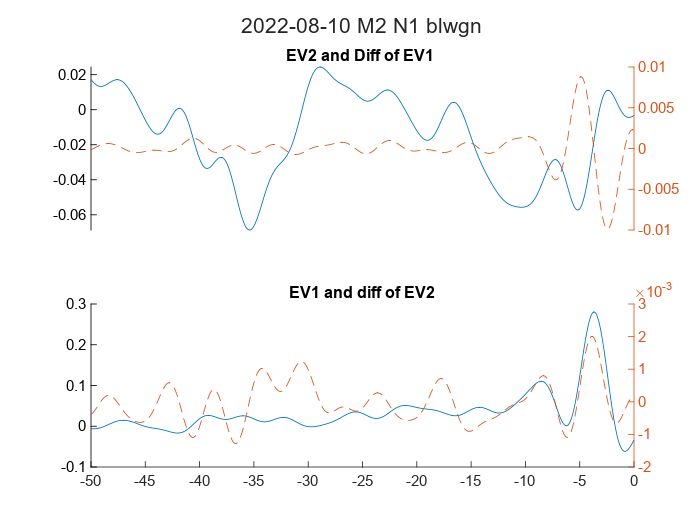

i = 10

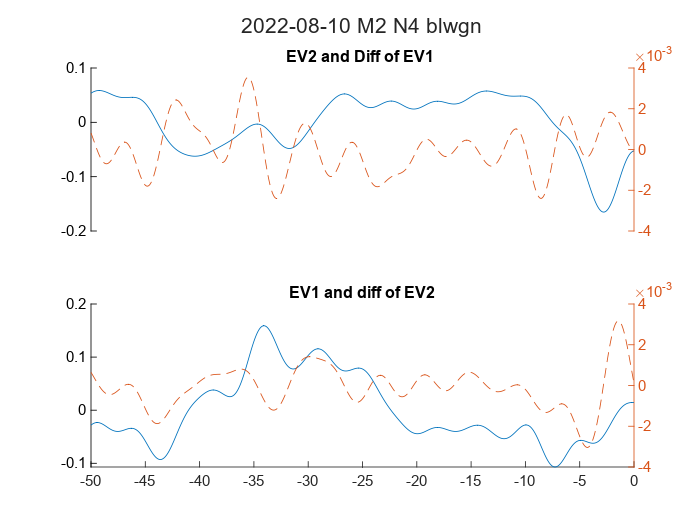

i = 11

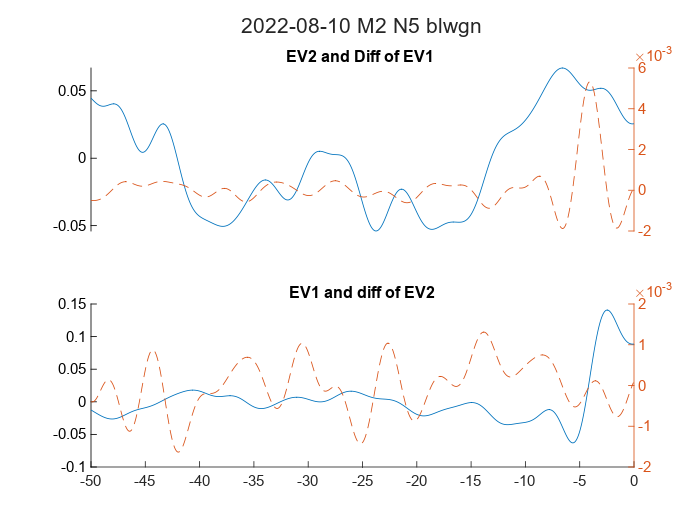

i = 12

i = 13

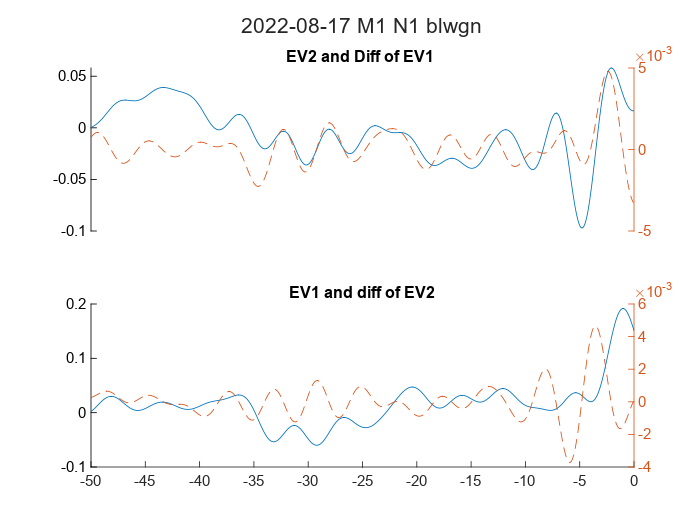

i = 14

i = 15

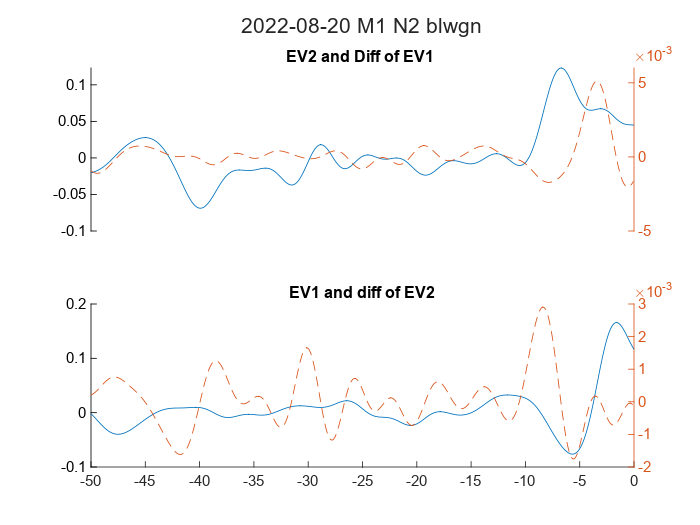

i = 16

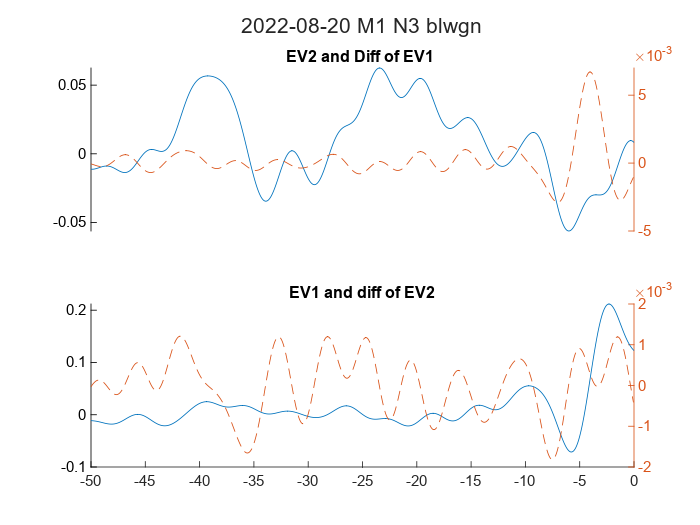

i = 17

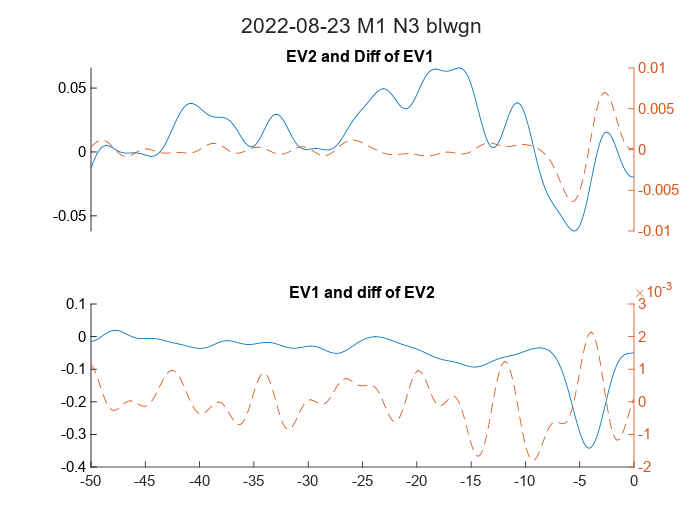

i = 18

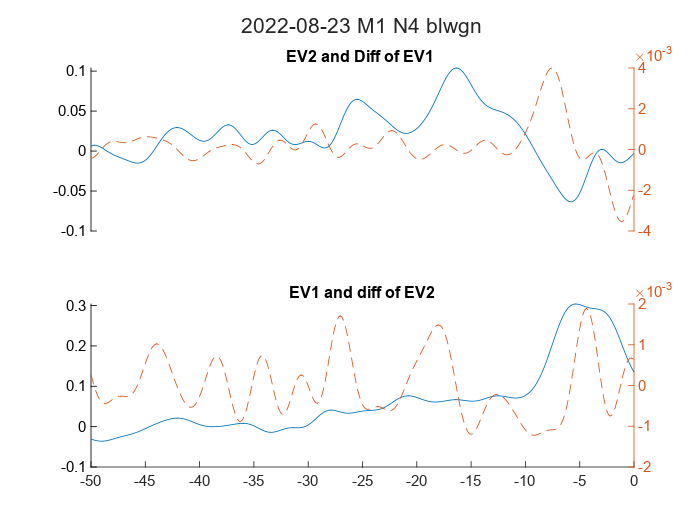

i = 19

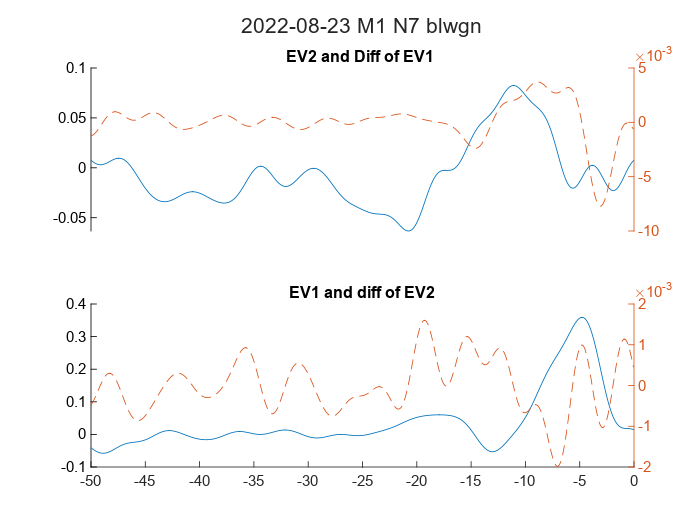

i = 20

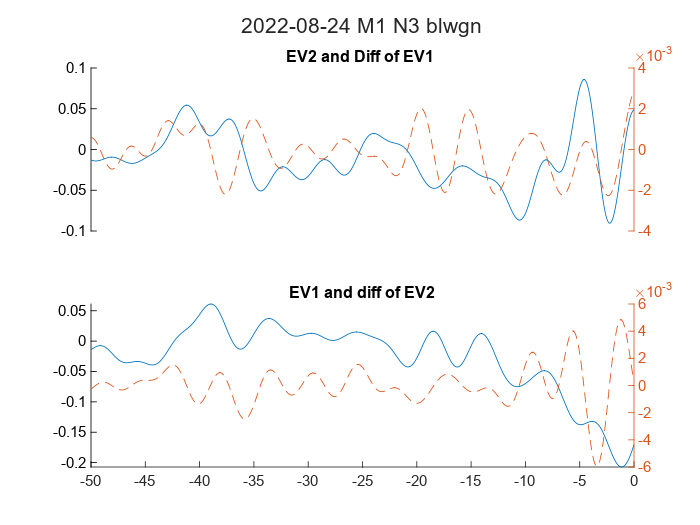

i = 21

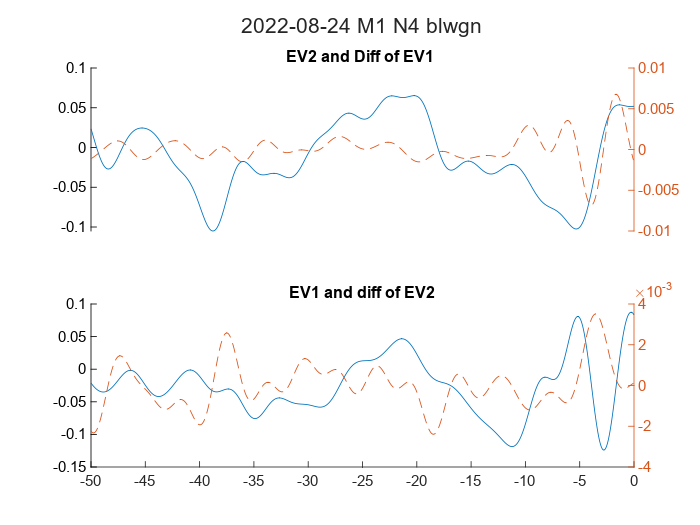

i = 22

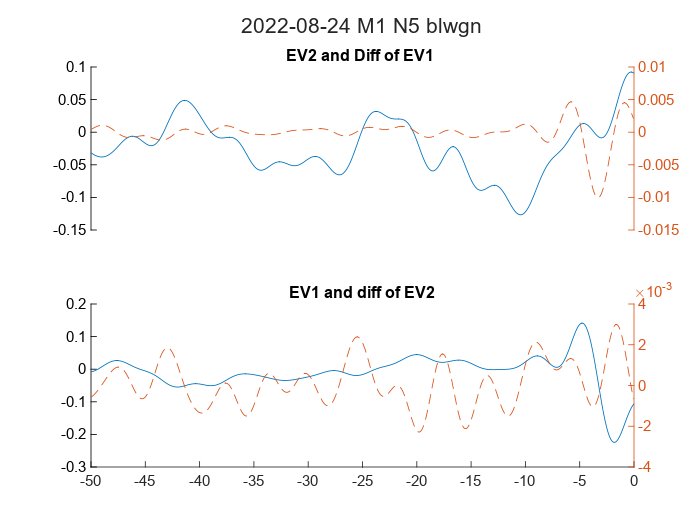

i = 23

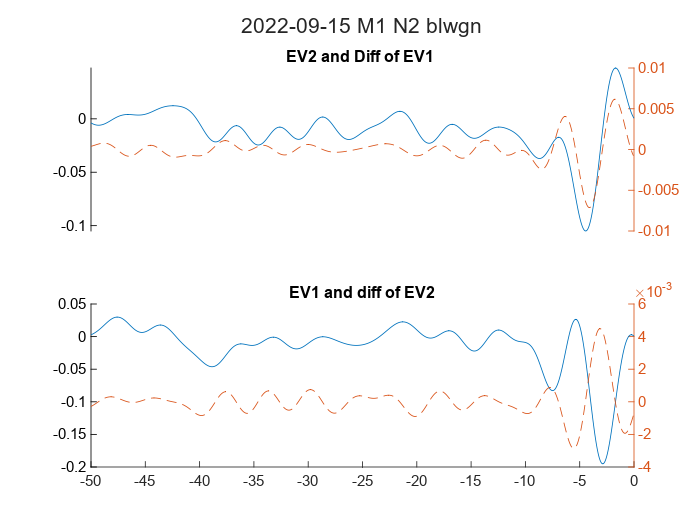

i = 24

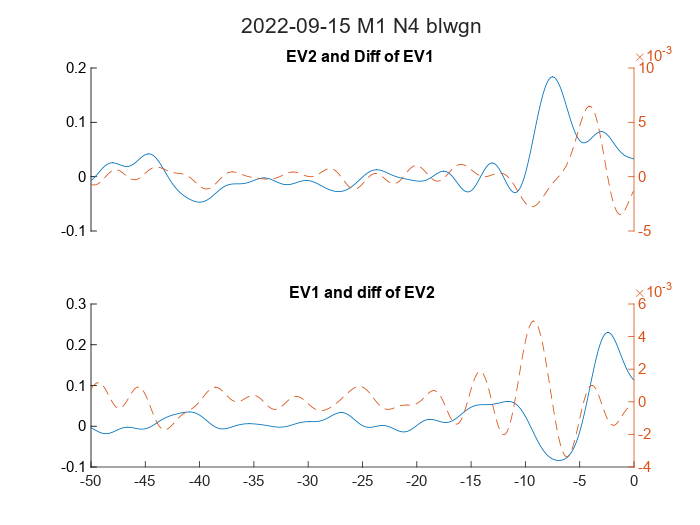

i = 25

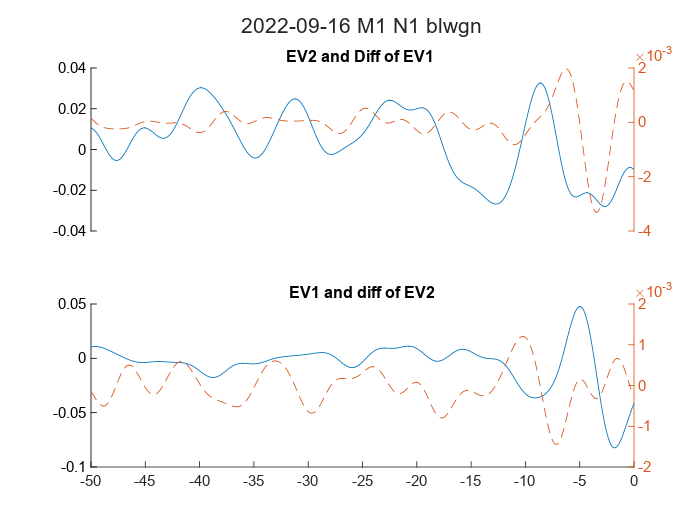

i = 26

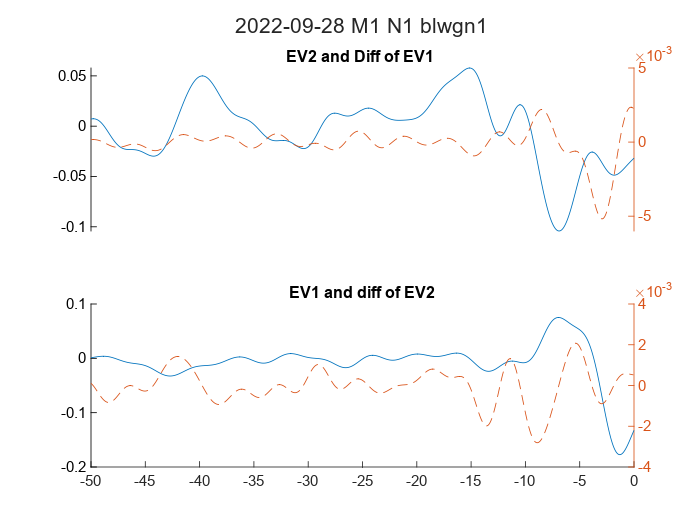

i = 27

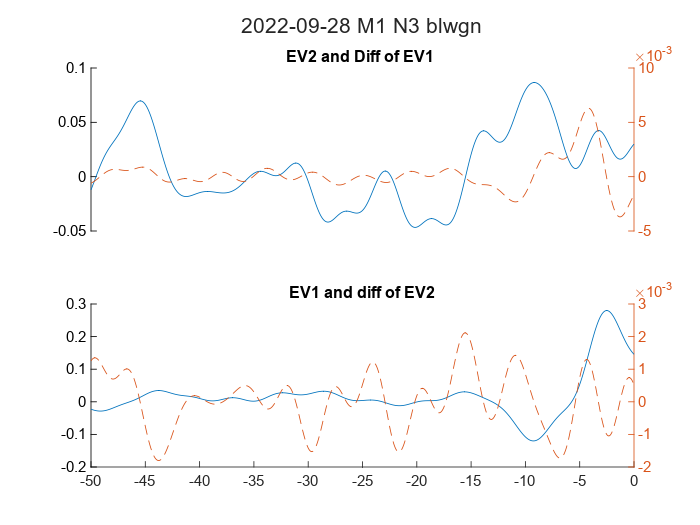

i = 28

i = 29

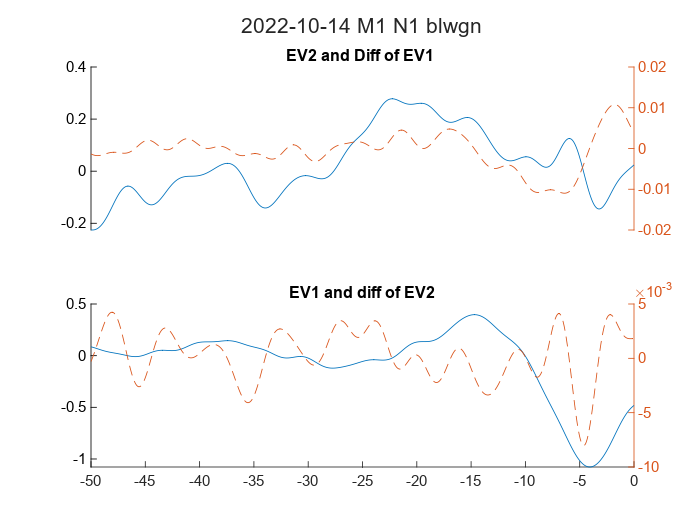

i = 30

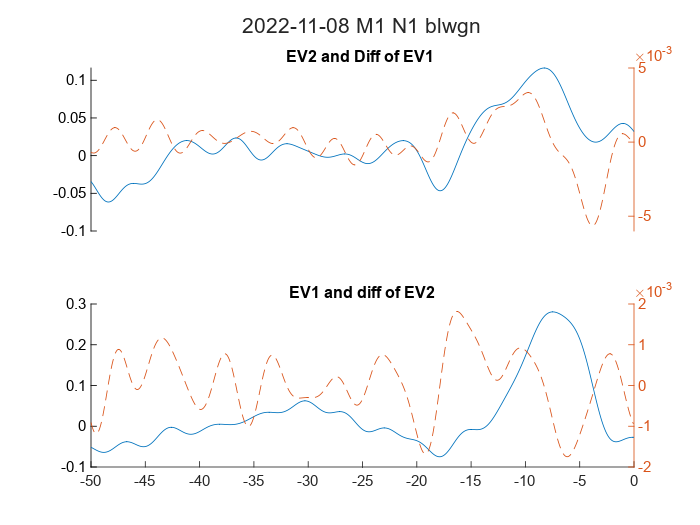

for i = 1:height(T_STA_EV)
    i
    ev = cell2mat(T_STA_EV.EV(i));
    if (size(ev,2))>1
        figure;
        tiledlayout(2,1)
        
        nexttile;
        plot(t, ev(:,2)); hold on;
        yyaxis right; plot(t(1:end-1), diff(ev(:,1)), 'Color','#D95319','LineStyle', '--');
        title('EV2 and Diff of EV1 ')
        box off;
        set(gca().XAxis, 'Visible', 'off');
        nexttile;
        plot(t, ev(:,1)); hold on;
        yyaxis right; 
        plot(t(1:end-1), diff(ev(:,2)),'Color','#D95319','LineStyle', '--');
        title('EV1 and diff of EV2')
        box off;

        sgtitle(replace(join([T_STA_EV.date(i) T_STA_EV.filename(i)]," "), "_", " "));
    end
    
end